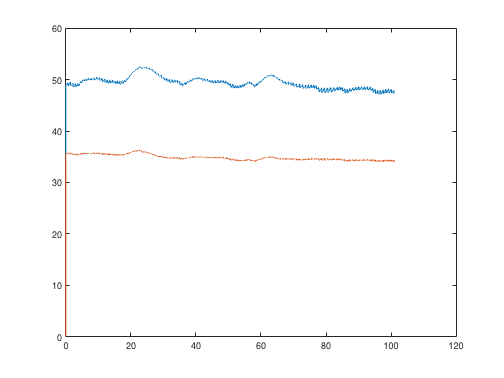

addpath('application/')
ADC_bits = 14;
V_ADC = 3.3;
Fs = 125;

R = sample(:,1)./(2^ADC_bits-1).*V_ADC;
IR = sample(:,2)./(2^ADC_bits-1).*V_ADC;
t = linspace(0,length(R)/Fs, length(R));

clf
plot(t,R)
hold on
plot(t, IR)


[ppg_sig, SpO2, ratio] = getPPGfromChannels(sample2(:,1), sample2(:,2));

ppg_sig = processRawPPG(ppg_sig);

if(~isempty(ppg_sig))
    SpO2
    resp_rate =  getRespiratoryRateFreq(t, ppg_sig)*60
    [sys,dias,feet] = findPPGPeaks(3.*ppg_sig, Fs);
    sortedFeatures = sortPPGPeaks(sys, dias, feet);
    hr = heartRateFromPPG(sortedFeatures(:,1), sortedFeatures(:,4),Fs)
    
    nnets.dbp = load('timeAndWidthFeats_DBP.mat').featNet_dbp;
    nnets.sbp = load('timeAndWidthFeats_SBP.mat').featNet_sbp;
    nnets.map = load('timeAndWidthFeats_MAP.mat').featNet_map;
    normFactors = load('NormalisationFactors.mat').normFactors;
    nnets.abpScale = normFactors('ABPAmpScale');
    nnets.abpMean = normFactors('ABPAmpMean');
    
    inputFeats = getInputFeatures(ppg_sig,125)
    sbp = predict(nnets.sbp, inputFeats).*nnets.abpScale + nnets.abpMean
    
    dbp = predict(nnets.dbp, inputFeats).*nnets.abpScale + nnets.abpMean
    
    map = predict(nnets.map, inputFeats).*nnets.abpScale + nnets.abpMean
end

SpO2 = 95.3693

resp_rate = 9.8915

hr = 82.4887

AI, 0.676776 
CT, -0.060322 
DiasPeakAmp, 0.714267 
HR, 0.245687 
IPA, 0.357481 
PA, 0.119305 
RespRate, 0.161078 
SysPeakAmp, 0.671973 
deltaT, -0.127192 
feetAmp, 0.554153 
time01, 0.735769 
time02, 0.149846 
time03, 0.585923 
time04, 0.115615 
time05, 0.391692 
time06, 0.101231 
time07, 0.322615 
time08, 0.095154 
time09, 0.285462 
time10, 0.081769 
time11, 0.215154 
time12, 0.067000 
time13, 0.131000 
time14, 0.059154 
time15, 0.075231 
time16, 0.039077 
time17, -0.045769 
time18, 0.507308 
time19, 0.423846 
time20, 0.380615 
time21, 0.296923 
time22, 0.198000 
time23, 0.134385 
time24, -0.006692 
time25, 3.579211 
time26, 3.404561 
time27, 3.217824 
time28, 2.875041 
time29, 2.149701 
time30, 1.428692 
time31, -1.267689 


inputFeats =     0.6768   -0.0603    0.7143    0.2457    0.3575    0.1193    0.1611    0.6720   -0.1272    0.5542    0.7358    0.1498    0.5859    0.1156    0.3917    0.1012    0.3226    0.0952    0.2855    0.0818    0.2152    0.0670    0.1310    0.0592    0.0752    0.0391   -0.0458    0.5073    0.4238    0.3806    0.2969    0.1980    0.1344   -0.0067    3.5792    3.4046    3.2178    2.8750    2.1497    1.4287   -1.2677


sbp = 128.2888

dbp = 68.5842

map = 113.7245

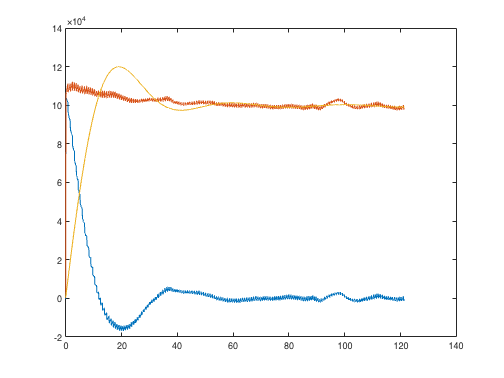

samp_freq =  mean(1./diff(t));
filt_design = designfilt('highpassiir','FilterOrder',4, ...
    'HalfPowerFrequency',0.05/samp_freq,'DesignMethod','butter');
R_ac =  filtfilt(filt_design, R);
R_dc = R-R_ac;

clf
plot(t, R_ac);
hold on
plot(t, R)
plot(t, R_dc)

R_dc = movmean(R, 500);
R_ac = R - R_dc;

IR_dc = movmean(IR, 500);
IR_ac = IR - IR_dc;

ratio = mean(R_ac)/mean(R_dc)*mean(IR_dc)/mean(IR_ac)

ratio = 1.0445

104-17.*ratio

ans = 86.2441



samp_freq =  mean(1./diff(t));
filt_design = designfilt('highpassiir','FilterOrder',4, ...
    'HalfPowerFrequency',0.5/samp_freq,'DesignMethod','butter');

R_ac = filtfilt(filt_design, R);
R_dc = R-R_ac;

IR_ac = filtfilt(filt_design,IR);
IR_dc = IR - IR_ac;

ratio = mean(R_ac)/mean(R_dc)*mean(IR_dc)/mean(IR_ac)

ratio = 0.7963

104-17.*ratio

ans = 90.4625

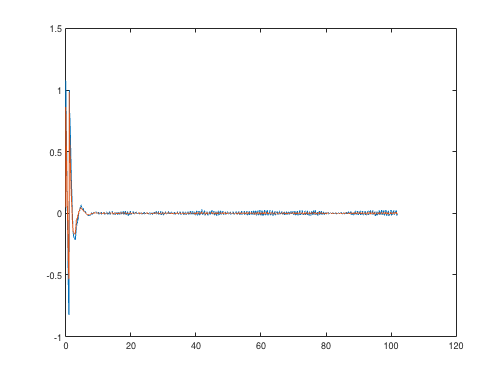


clf
plot(t, R_ac)
hold on
plot(t, IR_ac)

[~, lowerR] = envelope(R, 400, 'peak');
R_ac = R - lowerR;
[~, lowerIR] = envelope(IR, 400, 'peak');
IR_ac = IR - lowerIR;

ratio = mean(R_ac)/mean(lowerR)*mean(lowerIR)/mean(IR_ac)

ratio = 2.0765

104-17./ratio

ans = 95.8130

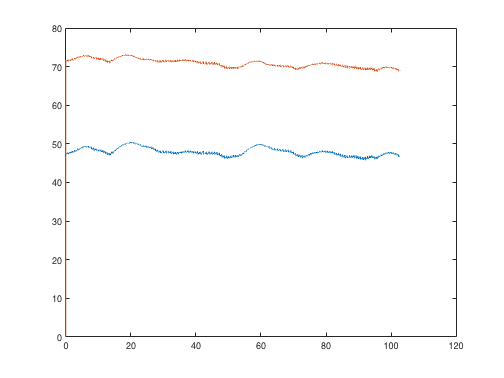


% clf
% plot(t(100:end),IR(100:end))
% hold on
% 
% plot(t(100:end), lowerIR(100:end))
clf
plot(t, R)
hold on 
plot(t, IR.*ratio)